802.11ac SEM using interpolation

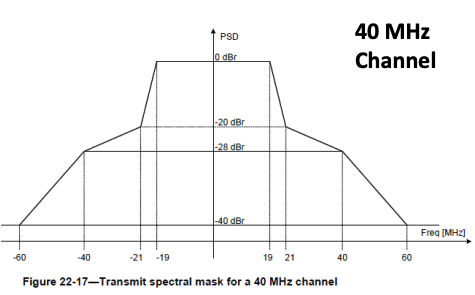

function SEM = ac_interpolate(Ts, B)
   % Generate only the positive part
   fTs = linspace(0, 60, 30/Ts);
   unscaled_SEM = zeros(length(fTs), 1);
    
   % unscaled SEM
   % max_fTs = 60 Mhz
   for idx = 1:length(fTs)
       if fTs(idx) < 19
           % freq: 0~19 MHz
           unscaled_SEM(idx) = 0;
       elseif fTs(idx) < 21
           % freq: 19~21 MHz
           unscaled_SEM(idx) = -10 * (fTs(idx) - 19);
       elseif fTs(idx) < 40
           % freq: 21~40 MHz
           unscaled_SEM(idx) = -20 -0.4211 * (fTs(idx) - 21);
       elseif fTs(idx) < 60
           % freq: 40~60 MHz
           unscaled_SEM(idx) = -28 -0.6 * (fTs(idx) - 40);
       else
           % freq: >60 MHz
           unscaled_SEM(idx) = -40;
       end
   end
    
   scale = B/40;
   
   SEM = unscaled_SEM;
   for idx = 2:length(fTs)-1
        SEM(idx) = SEM
   end
    
   % Generate the negative part
   SEM = [flip(SEM); SEM];
end